# Comparison between Klipp's method and the traditional approach

## Introduction

The traditional way to compute the friction velocity $u_*$ is after application of the anemoemter tilt correction as:


$$u_{*} = \left( \overline{u^{\prime}w^{\prime}}^{2}+\overline{v^{\prime}w^{\prime}}^{2}\right)^{1/4}$$


Klipp's method does not require knowledge of the instrument tilt. The method proposed by Klipp [1] is compared to the standard method, which is based on a direct calculation of the covariance between the three wind components. This comparison is done using the function "frictionVelocity" with an optional parameter named 'method', which is either 'standard' (by default) or 'Klipp2018'.

Klipp's method is described hereafter. sThe Reynold stress tensor is:


$$\mathit{\mathbf{R}}=\;\left\lbrack \begin{array}{ccc}
\overline{u^{\prime } u^{\prime } }  & \overline{u^{\prime } v^{\prime } }  & \overline{u^{\prime } w^{\prime } } \\
\overline{u^{\prime } v^{\prime } }  & \overline{v^{\prime } v^{\prime } }  & \overline{v^{\prime } w^{\prime } } \\
\overline{u^{\prime } w^{\prime } }  & \overline{v^{\prime } w}  & \overline{w^{\prime } w^{\prime } } 
\end{array}\right\rbrack$$


First, the eigen-value decomposition of the Reynolds stress tensor $\mathit{\mathbf{R}}$ is applied, leading to three eigen values  $\lambda_B > \lambda_M > \lambda_S$ and their associated eigenvectors $\bf{\Lambda_B}$,  $\bf{\Lambda_M}$ and $\bf{\Lambda_S}$. Then, the friction velocity is computed as:


$$u_{*_R} = \left[\left(\lambda_B-\lambda_S\right) \cos\left(\beta\right)\sin\left(\beta\right)\right]^{1/2}$$


where $\beta$ is the complement of the angle between the mean wind speed vector $\mathit{\mathbf{U}}$ and $\bf{\Lambda_S}$:


$$\beta = 90-\arccos\left( \frac{\bf{U} \cdot \bf{\Lambda_S}}{|\bf{\Lambda_S}| |\bf{U}|}\right)$$


 The angle $\beta$ need to be bounded between $0^{\circ }$ and ${90}^{\circ }$.

#### References

[1] Klipp, C. (2018). Turbulent friction velocity calculated from the Reynolds stress tensor.  Journal of the Atmospheric Sciences, (2018). 

## Generate tilted wind velocity records


clearvars;close all;clc;
% load simlated wind velocities
load('data.mat','u','v','w','t')
[M,N]=size(u);

yaw  = 45; % yaw angle (horizontal plane, between u and v)
elev = 10; % elevation angle (vertical plane, between w and u)
incl = 5; % inclination angle (vertical plane, between w and v)

R1 = [cosd(yaw),-sind(yaw),0;sind(yaw),cosd(yaw),0;0,0,1]; % matrix rotation around axis z
R2 = [cosd(elev),0,-sind(elev);0,1,0;sind(elev),0,cosd(elev)]; % matrix rotation around axis zy
R3 = [1,0,0; 0,cosd(incl),-sind(incl);0,sind(incl),cosd(incl)]; % matrix rotation around axis x

A = R3*R2*R1;  % 3D rotation matrix

% Construction of tilted velocity component
u_tilted = zeros(size(u));
v_tilted = zeros(size(u));
w_tilted = zeros(size(u));
for ii=1:M
    dummy = A\[u(ii,:);v(ii,:);w(ii,:)];
    u_tilted(ii,:) = dummy(1,:);
    v_tilted(ii,:) = dummy(2,:);
    w_tilted(ii,:) = dummy(3,:);
end

## Computation of the friction velocity

u_star2 = nan(1,M);
u_star1 = zeros(1,M);
R = nan(3,3,M);
for ii = 1:M
    [u_star2(ii)] = frictionVelocity(u_tilted(ii,:),v_tilted(ii,:),w_tilted(ii,:),'method','Klipp2018');
    [u_star1(ii)] = frictionVelocity(u(ii,:),v(ii,:),w(ii,:));
end

## Display the results

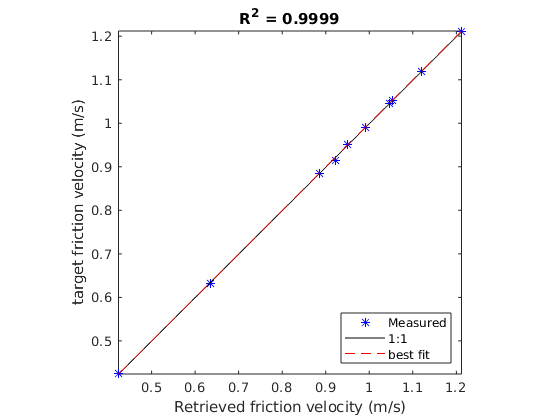

clf;close all;
fig5 = figure;
plot(u_star2,u_star1,'b*');
daspect([1 1 1])
hold on;box on;

p = polyfit(u_star2,u_star1,1);
x = linspace(nanmin(u_star2(:)),nanmax(u_star2(:)),2);
y = polyval(p,x);
plot(x,y,'k')
[r p] = corr(u_star2',u_star1');
title(['R^2 = ' num2str(r.^2,4)]) ; % Add the value of r to the plot.
plot([min([u_star1,u_star2]),max([u_star1,u_star2])],[min([u_star1,u_star2]),max([u_star1,u_star2])],'r--')
legend('Measured','1:1','best fit','location','southEast')
ylabel('target friction velocity (m/s)')
xlabel('Retrieved friction velocity (m/s)')
set(gcf,'color','w')
xlim([min([u_star1,u_star2]),max([u_star1,u_star2])])
ylim([min([u_star1,u_star2]),max([u_star1,u_star2])])